clear all;
zeta=0.42;
wn=1.905;
p1=30;
p2=40;
p3=50;

z1=2*zeta*wn;
z2=wn*wn;
 
k4=z1+p1+p2+p3;
k3=z2+z1*(p1+p2+p3)+(p1*p2+p2*p3+p1*p3);
k2=z2*(p1+p2+p3)+z1*(p1*p2+p2*p3+p1*p3)+p1*p2*p3;
k1=z2*(p1*p2+p2*p3+p1*p3)+z1*(p1*p2*p3);
k0=z2*p1*p2*p3;


M=[k4;k3;k2;k1;k0];
A=[0 0 0 0 1;6.2491 0 -17.36 0 0;0 6.24 0 -17.36 -30.17;-169.84591 0 0 0 0;0 -169.84591 0 0 0];
B=[0;-30.17;0;0;0];
D=(A)^(-1);
TF=D*(M-B);

G1=tf([0.4167 0 -11.3426],[1 0 -30.17 0 0]);
G2=tf(-1.157,[1 0 -30.17]);
a1=TF(1)

a1 = -665.7117

a0=TF(2)

a0 = -1.2820e+03

b1=TF(3)

b1 = -523.3826

b0=TF(4)

b0 = -4.5867e+03

p=TF(5)

p = 121.6002

C1=tf([TF(1),TF(2)],[1 TF(5)]);
C2=tf([TF(3),TF(4)],[1 TF(5)]);
P=G1*C1;
Q=G2*C2;
b=minreal(P+Q);
cltf=15*(b);
allmargin(cltf)

ans = struct with fields:
     GainMargin: [0.1077 Inf]
    GMFrequency: [5.0726 Inf]
    PhaseMargin: 51.5609
    PMFrequency: 39.6862
    DelayMargin: 0.0227
    DMFrequency: 39.6862
         Stable: 1


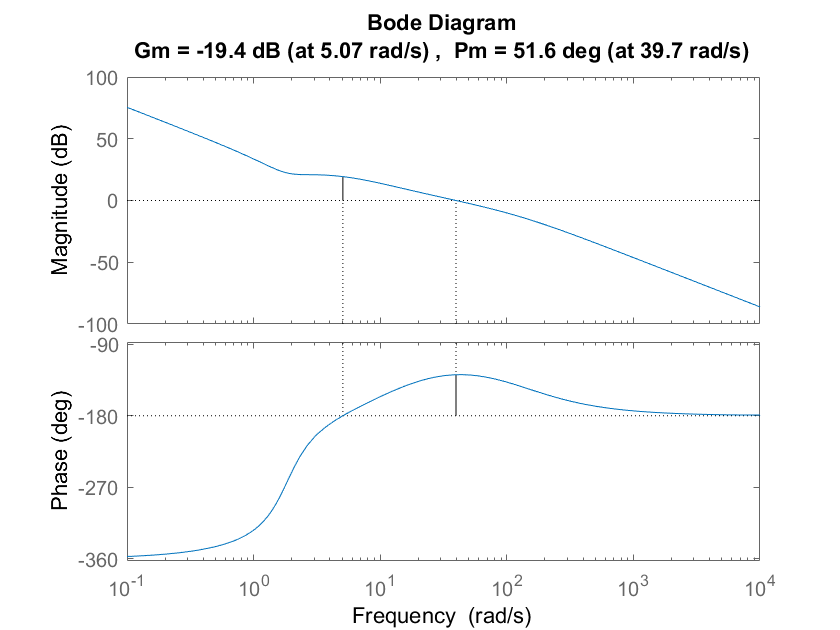

margin(cltf)